clc; clear;

stik = 40;     % Antal stikprøver
tests = 5;     % Antal terningekast / udtagelser af stikprøven
test_range = [30, 35];
step = 0.25;

ms = zeros(1, stik);
Y = zeros(stik, tests);

for i = 1:stik
    for j = 1:tests
        Y(i,j) = randi(test_range, 1);
    end
    ms(i) = mean(Y(i,:));
end


histogram(ms, min(test_range):step:max(test_range), "Normalization","pdf")
hold on

% Den gennemsnitlige afvigelse
mean_gns = mean(ms)

mean_gns = 32.3500

stdafv = std(ms, 1)

stdafv = 0.7082

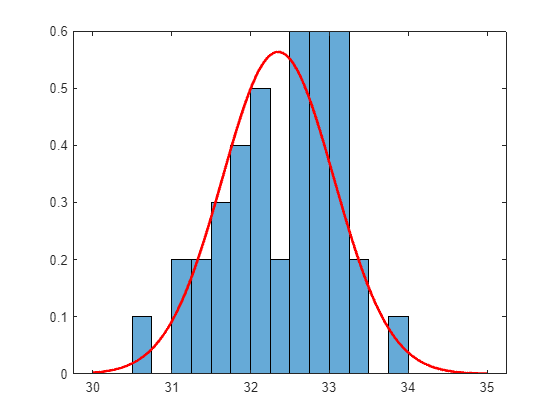


% PLotte fordelingen oveni
dist = makedist("Normal","mu",mean_gns,"sigma",stdafv);
x = linspace(min(test_range), max(test_range), 1000);

df = pdf(dist, x);

plot(x, df, Color="red", LineStyle="-", LineWidth=2)
hold off


rng default


dist2 = makedist("Normal", "mu",mean_gns,"sigma",stdafv)

dist2 =   NormalDistribution

  Normal distribution
       mu =    32.35
    sigma = 0.708167



df2 = random(dist2, stik, 1);


[h,p,stats] = chi2gof(df2,'Alpha', 0.05)

h = 0

p = 0.1671

stats = struct with fields:
    chi2stat: 5.0656
          df: 3
       edges: [30.2650 31.6507 32.1126 32.5745 33.0364 33.4984 34.8841]
           O: [8 4 5 12 6 5]
           E: [7.0106 5.8724 7.2726 7.2398 5.7934 6.8112]
